% Ruta de la carpeta principal
rutaPrincipal = 'animals_dataset/animals/animals';

% Obtener lista de subcarpetas
subcarpetas = dir(fullfile(rutaPrincipal, '*'));
subcarpetas = subcarpetas([subcarpetas.isdir] & ~strcmp({subcarpetas.name}, '.' ) & ~strcmp({subcarpetas.name}, '..'));

% Inicializar variables para almacenar resultados
archivoAleatorioPorCarpeta = cell(numel(subcarpetas), 1);
imagenAleatoriaPorCarpeta = cell(numel(subcarpetas), 1);

% Recorrer cada subcarpeta
for i = 1:numel(subcarpetas)
    carpetaActual = fullfile(rutaPrincipal, subcarpetas(i).name);

    % Obtener lista de imágenes en la subcarpeta
    imagenes = dir(fullfile(carpetaActual, '*.jpg')); % Puedes cambiar la extensión según tus necesidades

    % Seleccionar una imagen aleatoria
    idxImagenAleatoria = randperm(numel(imagenes), 1);
    archivo_imagen_aleatoria = fullfile(carpetaActual, imagenes(idxImagenAleatoria).name);
    archivoAleatorioPorCarpeta{i} = archivo_imagen_aleatoria;
    imagen = imread(archivo_imagen_aleatoria);
    imagenAleatoriaPorCarpeta{i} = imagen;
end

% Seleccionar una carpeta aleatoria
idxCarpetaAleatoria = randperm(numel(subcarpetas), 1);
carpetaAleatoria = fullfile(rutaPrincipal, subcarpetas(idxCarpetaAleatoria).name);

% Seleccionar una imagen aleatoria dentro de la carpeta aleatoria
imagenesEnCarpetaAleatoria = dir(fullfile(carpetaAleatoria, '*.jpg')); % Puedes cambiar la extensión según tus necesidades
run = true

run = logical
   1


while run
    idxImagenAleatoriaEnCarpetaAleatoria = randperm(numel(imagenesEnCarpetaAleatoria), 1);
    archivo_imagenrandom = fullfile(carpetaAleatoria, imagenesEnCarpetaAleatoria(idxImagenAleatoriaEnCarpetaAleatoria).name)
    archivoAleatorioPorCarpeta{idxCarpetaAleatoria}
    if ~strcmp(archivo_imagenrandom,archivoAleatorioPorCarpeta{idxCarpetaAleatoria})
        run = false;
        imagen_random = imread(archivo_imagenrandom);
    end
end

archivo_imagenrandom = 'animals_dataset\animals\animals\owl\6e8ce60e91.jpg'

ans = 'animals_dataset\animals\animals\owl\05fe394a81.jpg'

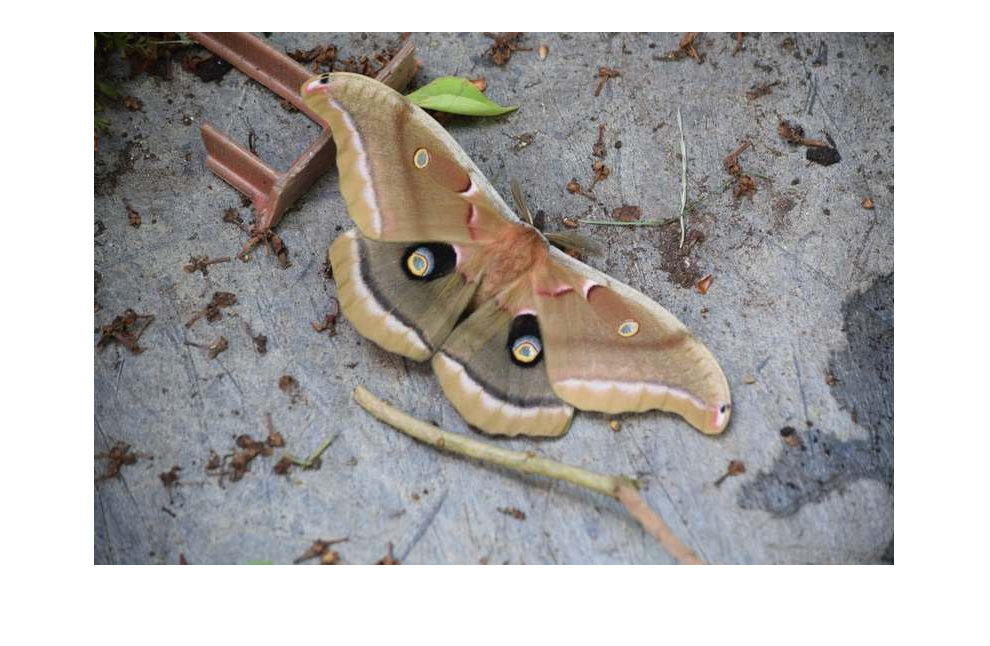

% Mostrar resultados
imshow(imagenAleatoriaPorCarpeta{51})

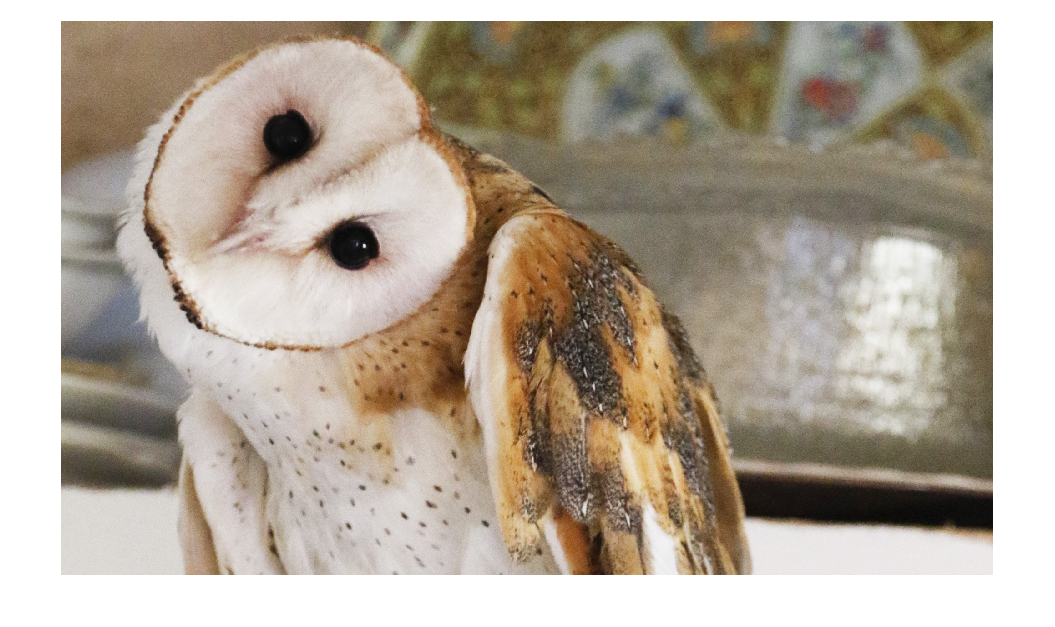

imshow(imagen_random)

detectarAnimales(imagenAleatoriaPorCarpeta, imagen_random)

ans = 51

function clase = detectarAnimales(imagenes, im2)
    % Inicializar el array de resultados
    resultados = zeros(1, numel(imagenes));

    % Extraer canales de color de la imagen fija (im2)
    im2_r = im2(:,:,1);
    im2_g = im2(:,:,2);
    im2_b = im2(:,:,3);

    % Calcular histogramas y normalización para Imagen fija (im2)
    hist_im2_r = imhist(im2_r);
    hist_im2_norm_r = hist_im2_r/numel(im2_r);

    hist_im2_g = imhist(im2_g);
    hist_im2_norm_g = hist_im2_g/numel(im2_g);

    hist_im2_b = imhist(im2_b);
    hist_im2_norm_b = hist_im2_b/numel(im2_b);

    % Iterar sobre todas las imágenes en el array
    for i = 1:numel(imagenes)
        % Extraer canales de color de la imagen actual (im1)
        im1 = imagenes{i};
        im1_r = im1(:,:,1);
        im1_g = im1(:,:,2);
        im1_b = im1(:,:,3);

        % Calcular histogramas y normalización para la imagen actual (im1)
        hist_im1_r = imhist(im1_r);
        hist_im1_norm_r = hist_im1_r/numel(im1_r);

        hist_im1_g = imhist(im1_g);
        hist_im1_norm_g = hist_im1_g/numel(im1_g);

        hist_im1_b = imhist(im1_b);
        hist_im1_norm_b = hist_im1_b/numel(im1_b);

        % Calcular divergencia de Jeffrey para cada canal
        divergencia_jeffrey_r = sum(hist_im1_norm_r .* log((hist_im1_norm_r + eps) ./ (hist_im2_norm_r + eps) + eps));
        divergencia_jeffrey_g = sum(hist_im1_norm_g .* log((hist_im1_norm_g + eps) ./ (hist_im2_norm_g + eps) + eps));
        divergencia_jeffrey_b = sum(hist_im1_norm_b .* log((hist_im1_norm_b + eps) ./ (hist_im2_norm_b + eps) + eps));

        % Calcular la media de las divergencias de los canales
        d = mean([divergencia_jeffrey_r, divergencia_jeffrey_g, divergencia_jeffrey_b]);

        % Almacenar el resultado en el array de resultados
        resultados(i) = d;
    end
    [minimo,clase] = min(resultados);
end